# **Experiência 5 - Como inserir marca d’água em um sinal de áudio? **

## **Guilherme Reis da Silva 10773700**

## **Gabriel Tavares Ferrarez 10773801** 

# PARTE 1 - Sistema de marca d’água visto como um problema de comunicação digital

## LETRA A

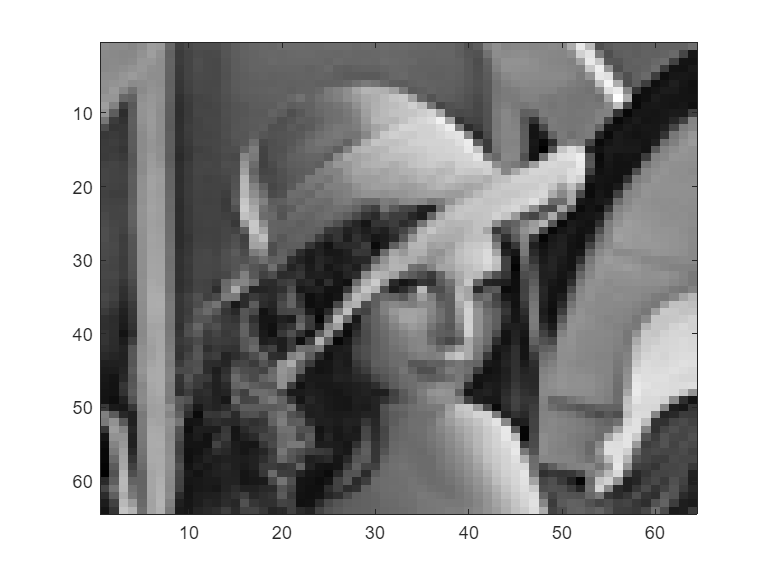

lenna = imread('lenna64.jpg');
imagesc(lenna);
colormap(gray);

load('fspecial_matriz.mat');

M = 64*64*8;

lenna_bin = dec2bin(lenna);
lenna_col = reshape(lenna_bin,2^15,1);
am = 2*str2num(lenna_col) - 1;

## LETRA B

fa = 44.1e3;
R = 100;
g = 1;
rand('seed',12345);
Nb = fa / R;

c = 2*round(rand(Nb,1)) - 1; % codigo

v = kron(am,c); % sinal modulado
bm_exp = kron(am, ones(Nb,1)); %repetir cada ponto do am Nb vezes

## LETRA C

## LETRA D

## LETRA E

## LETRA F

## LETRA G

# PARTE 2 - Ajuste do ganho para detecção sem erro

## LETRA A

[musica, fs] = audioread('BeethovenExp5.wav');



% sound(musica(fs*5:fs*15),fs)

% sound(y(fa*5:fa*20), fs);

## LETRA B

x = musica;

## LETRA C

# PARTE 3 - Tornando a marca d’água inaudível

## LETRA A

w = zeros(length(musica),1);
z = zeros(length(musica),1);
zs = zeros(50,1);
Nblocos = floor(length(musica)/512);

for i = (0:Nblocos-1)
    mascara = psychoacoustical_model( musica(i*512+1 : (i+1)*512) );
    [b0, ai] = shaping_filter_design(mascara, 50);
    [w(i*512+1: (i+1)*512), zs] = filter(b0, ai ,v(i*512+1: (i+1)*512), zs);

    y(i*512+1: (i+1)*512) = w(i*512+1: (i+1)*512) + x(i*512+1: (i+1)*512);
end

## LETRA B

zs = zeros(50,1);
for i = (0: floor(length(musica)/512 - 1))
    mascara = psychoacoustical_model( y(i*512+1: (i+1)*512) );
    [b0, ai] = shaping_filter_design(mascara, 50);
    [z(i*512+1: (i+1)*512), zs]= filter(ai, b0 ,y(i*512+1: (i+1)*512), zs);
end

ym = reshape(z,Nb,32768);

alfam = transpose(ym)*c/Nb;
BER = sum(abs(sign(alfam) - am)/2)/length(am)

BER = 0.2490


b_chapeu = sign(alfam);
lenna_col_chapeu = num2str((b_chapeu + 1)/2);
lenna_bin_chapeu = reshape(lenna_col_chapeu, 64*64, 8);
lenna_chapeu = bin2dec(lenna_bin_chapeu);
nova_lenna = reshape(lenna_chapeu, 64,64);

% figure()
% colormap(gray)
% imagesc(nova_lenna)

mssim = ssim_index(lenna, nova_lenna, [0.01 0.03], matriz, 255)

Unrecognized function or variable 'matriz'.

% sound(z(fa*5:fa*15), fs)

# PARTE 4 - Marca d’água inaudível com BER baixa

Nfiltro = 50;
correlacao_v= xcorr(v,Nfiltro,'biased');

zs = zeros(2*Nfiltro,1);
pre_dem = zeros(length(musica),1);
saidaWiener = zeros(length(musica),1);

Nblocos = floor(length(musica)/512);

for i = (0: Nblocos-1)
    correlacao_z = xcorr(z(i*512+1: (i+1)*512), 2*Nfiltro, 'biased');
    
    autocorr_z = toeplitz(correlacao_z(2*Nfiltro+1:end));
    
    h = autocorr_z\correlacao_v;
    
    [saidaWiener(i*512+1: (i+1)*512), zs] = filter(h,1,z(i*512+1: (i+1)*512), zs);
    pot_Wiener = sum(saidaWiener(i*512+1: (i+1)*512).*saidaWiener(i*512+1: (i+1)*512))/512;
    
    if pot_Wiener > 0
        saidaWiener(i*512+1: (i+1)*512) = saidaWiener(i*512+1: (i+1)*512)/sqrt(pot_Wiener);
    end
    
end

pre_dem(1:end-Nfiltro) = saidaWiener(Nfiltro+1:end);

% 
% plot(pre_dem)
Nblocos*512

ym = reshape(pre_dem,Nb,32768);

alfam = transpose(ym)*c/Nb;
BER = sum(abs(sign(alfam) - am)/2)/length(am)

b_chapeu = sign(alfam);
lenna_col_chapeu = num2str((b_chapeu + 1)/2,"%1.0f");

plot(lenna_col_chapeu - lenna_col)


lenna_bin_chapeu = reshape(lenna_col_chapeu, 64*64, 8);
lenna_chapeu = bin2dec(lenna_bin_chapeu);
nova_lenna = reshape(lenna_chapeu, 64,64);

figure()
colormap(gray)
imagesc(nova_lenna)

%0,35
mssim = ssim_index(lenna, nova_lenna, [0.01 0.03], matriz, 255)

% sound(z(5*fs:15*fs),fs)